addpath('Utility_functions')
set(0, 'DefaultAxesFontName', 'Times New Roman');
set(0, 'DefaultTextFontName', 'Times New Roman');

folder = '..\..\Data\pointtargets';

files = dir(folder);
files = files(3:end);
filesfmc = files([1]);
filesrayline = files([2]);

load("..\..\Data\USclutterdata\L22_14systeminfo.mat")
xs = ((-(Trans.numelements/2 -1):(Trans.numelements/2))-0.5)*Trans.spacingMm;
fs = Receive(1).decimSampleRate;
dt = 1/fs;
dz = dt*1.48/2;

% delays = [0.41 0.4 0.41 0.40 0.38 0.4 0.4; ...
%     0.37 0.39 0.40 0.39 0.39 0.36 0.41]
delay = 0.0;
% delays = [0.3472 0.3472 0 0 0 0];

irms = cell(1,1);
rms = cell(1,2);
tic;
% delays = [0.37088 0.39456 0.41824 0.37088 0.41824 0.4064 0.39456 0.39456 0.38272 0.39456 0.37088 0.37088 0.3472 0.41824];
% delays = [0.3274];
delays = [0.31168];
for i=1:1
    S = load(fullfile(folder,filesfmc(i).name));
    irm = RFtoRM(S.RcvData,S.Receive);
    irm = circshift(irm,-floor(delays(i)/dz),3);
    irms{i} = irm;
    rm = FMCtoFocused_frequency(irm,1.48,Receive,Trans,8,6,'a_shrink','boxcar');
    % rm = FMCtoFocused_time(irm,1.48,Receive,Trans,8,6,'a_shrink','boxcar');
    rms{i,1} = rm;
end

nelems = 13

delays = [0.32352];
for i=1:1
    S = load(fullfile(folder,filesrayline(i).name));
    rm = RFtoRM(S.RcvData,S.Receive);
    rm = circshift(rm,-floor(delays(i)/dz),3);
    rms{i,2} = rm;
end
t = toc;
t/60

ans = 0.2952


len = length(irms{1});
ts = dt*(0:(len-1));
zs = 1.48*ts/2;

% save irmandrms.mat irms rms len ts zs xs fs dt dz -v7.3

% load irmandrms.mat

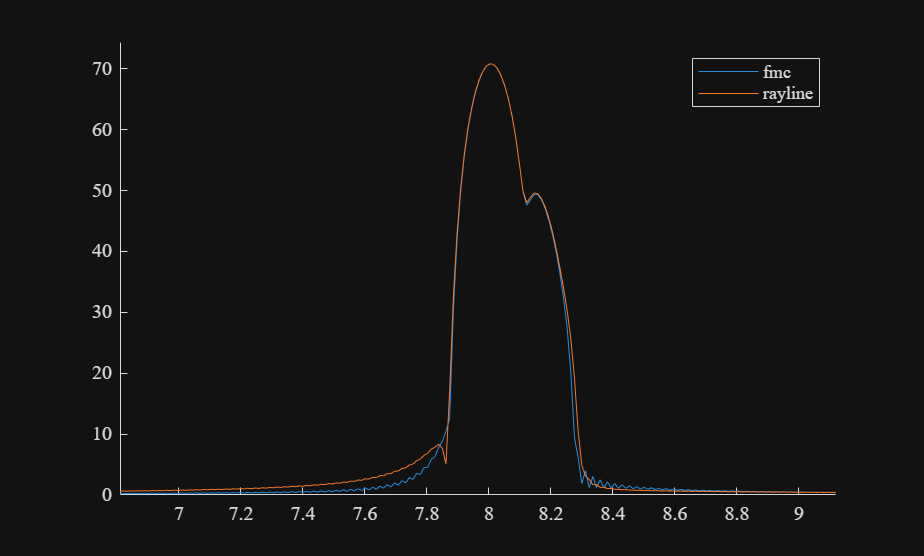

labels = {'fmc','rayline'};

figure()
hold on
% noise_level_fmc = 0;
% subset = [2 4 6 8];
subset = 1:2;
for i=subset
% figure()

% rm = irms{i};
rm = rms{1,i};
elems = 64;
ave = zeros(len,1);
for j=elems
    ave = ave + 20*log10(abs(squeeze(rm(j,j,1:len)))+1);
end
ave = ave / length(elems);
plot(zs(1:len),ave)
% plot(ave)
% title(labels{lab})
% noise_level_fmc = noise_level_fmc + mean(ave(100:600))/14;
end
hold off

legend(labels(subset))

xlim([6.81 9.12])
ylim([0.0 74.4])

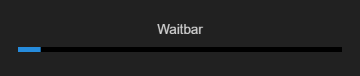

rfnums = 1:6;
% rfnums = [12]
beamformed = cell(1,2,length(rfnums));      % material; rayline dry, rayline wet, safb dry, safb wet; rfnums
wb = waitbar(0);
for i=1:1
    for j=1:2
        % waitbar(((i-1)*2 + j) / 28,wb)
        
        rm = rms{i,j};
        
        for k=1:length(rfnums)
            waitbar(((i-1)*2 + (j-1)*6 +k) / (28*6),wb)
            [das_data,~,~] = das(rm,0,1.48,Trans,Receive,8,rfnums(k),'a_shrink','boxcar');
            beamformed{i,j,k} = das_data;
        end
    end
end

labels = {'Syntetic Aperture','Rayline'}; 
figure()
tiledlayout(1,2,'TileSpacing','tight','Padding','tight');
nexttile;
hold on
lab = 1;
subset = 1:2;
zmask = zs > 7 & zs < 9;
for i=subset
% figure()
% das_data = beamformed{i,2};
zsinterp = linspace(min(zs(zmask)),max(zs(zmask)),20000);
das_data = beamformed{1,i,2};
zinterpprofile = interp1(zs(zmask),20*log10(abs(squeeze(das_data(64,zmask)))'+1),zsinterp,'cubic');
i1 = find(zinterpprofile>(max(zinterpprofile)-3),1,"first");
i2 = find(zinterpprofile>(max(zinterpprofile)-3),1,"last");
if i==1
    disp(['FMC axial fwhm = ' num2str(zsinterp(i2) - zsinterp(i1)) 'mm']);
    plot(zsinterp,zinterpprofile - max(zinterpprofile),'LineWidth',2)
else
    disp(['Ray axial fwhm = ' num2str(zsinterp(i2) - zsinterp(i1)) 'mm']);
    plot(zsinterp,zinterpprofile - max(zinterpprofile),'LineWidth',2,'LineStyle','--')
end
ylim([-70 1])
ylabel('Intensity (dB)')
% title(labels{lab})
lab=lab+1;
end

FMC axial fwhm = 0.082155mm


Ray axial fwhm = 0.082354mm


hold off

legend(labels(subset))
xlabel('z (mm)')
title('Axial Profile of PSF (a)')

nexttile;
xmask = xs > (-0.05-1) & xs < (-0.05+1);
zind = find(min(abs(zs-8)) == abs(zs-8));
hold on
% for i=subset
% figure()
% das_data = beamformed{i,2};
xsinterp = linspace(min(xs(xmask)),max(xs(xmask)),20000);
das_data = beamformed{1,1,2};
% y = 20*log10(abs(squeeze(das_data(:,zind)))'+1);
interpprofile = interp1(xs(xmask),20*log10(abs(squeeze(das_data(xmask,zind)))'+1),xsinterp,"cubic");
plot(xsinterp,interpprofile - max(interpprofile),'LineWidth',2)
ylim([-70 1])
i1 = find(interpprofile>(max(interpprofile)-3),1,"first");
i2 = find(interpprofile>(max(interpprofile)-3),1,"last");
disp(['FMC lateral fwhm = ' num2str(xsinterp(i2) - xsinterp(i1)) 'mm']);

FMC lateral fwhm = 0.1495mm




das_data = beamformed{1,2,2};

interpprofile = interp1(xs(xmask),20*log10(abs(squeeze(das_data(xmask,zind)))'+1),xsinterp,'cubic');
plot(xsinterp,interpprofile - max(interpprofile),'LineWidth',2,'LineStyle','--')
ylim([-70 1])
i1 = find(interpprofile>(max(interpprofile)-3),1,"first");
i2 = find(interpprofile>(max(interpprofile)-3),1,"last");
disp(['Ray lateral fwhm = ' num2str(xsinterp(i2) - xsinterp(i1)) 'mm']);

Ray lateral fwhm = 0.14932mm


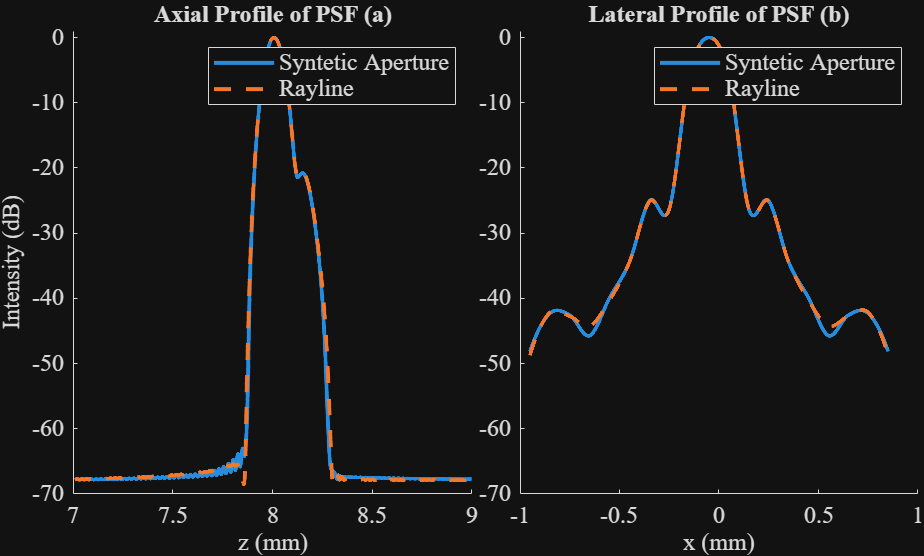



% end
hold off
title('Lateral Profile of PSF (b)')
legend(labels(subset))
xlabel('x (mm)')
fontsize(12,'points')

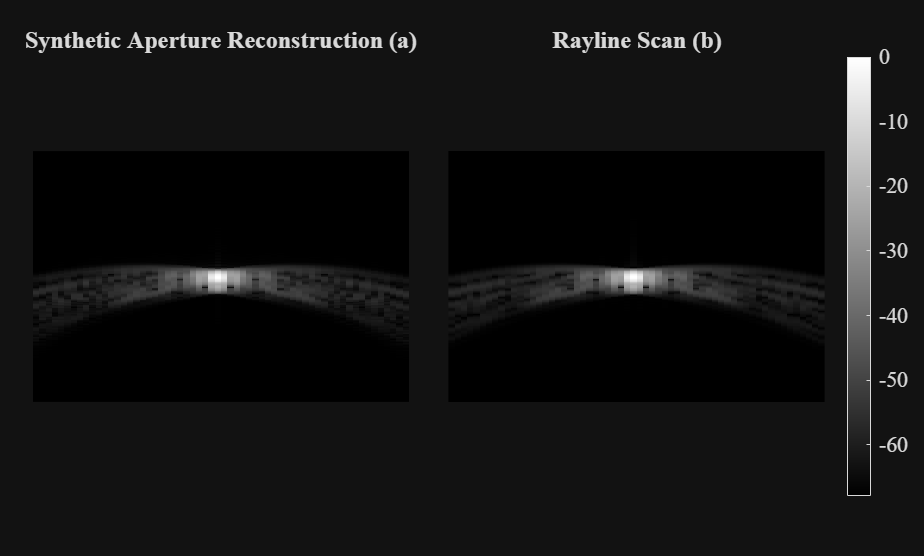

zmask = zs > 6 & zs < 10;
xmask = xs > -3 & xs < 3;
figure()
tiledlayout(1,2,'TileSpacing','tight','Padding','tight');
nexttile;
imagesc(xs(xmask),zs(zmask),20*log10(abs(beamformed{1,1,2}(xmask,zmask)).'+1)- max(max(20*log10(abs(beamformed{1,1,2}(xmask,zmask)).'+1))))
colormap gray
axis equal
axis off
title('Synthetic Aperture Reconstruction (a)')
nexttile;
imagesc(xs(xmask),zs(zmask),20*log10(abs(beamformed{1,2,2}(xmask,zmask)).'+1) - max(max(20*log10(abs(beamformed{1,2,2}(xmask,zmask)).'+1))))
colormap gray
axis equal
axis off
title('Rayline Scan (b)')
fontsize(12,'points')
colorbar

zsmaskint = zs >7.4 & zs <7.85;
clutterdb = zeros(14,2,6,41);
signaldb = zeros(14,2,6,41);

for k=1:6; %fnumber for reception beamforming
for l=1:2; %1-> fmc, 2-> rayline
subset = 1:14;
for i=subset

das_data = beamformed{i,l,k};

elems = 64 + (-20:20);
% elems = 64;

for j=elems
    clutterdb(i,l,k,j-43) = mean(20*log10(abs(squeeze(das_data(j,zsmaskint)))'+1) - noise_levels_bmode(l,k));
    signaldb(i,l,k,j-43) = 20*log10(abs(squeeze(das_data(j, 677)))'+1) - noise_levels_bmode(l,k);
end

end
end
end

Unrecognized function or variable 'noise_levels_bmode'.

%first dim: material and dryness
%second dim: fmc or rayline
%third dim: receive fnum
%fourth dim: bmode average value in region

clutterdb_ave = mean(clutterdb,4);
clutterdb_std = std(clutterdb,0,4);
signaldb_ave = mean(signaldb,4);

figure()
tiledlayout(1,7);
titles ={'coc','glass','ibidi','pc','pet','pmma','pmp'};
for i=[2 1 3 4 5 6 7]
    nexttile;
    hold on
    errorbar(1:6,squeeze(clutterdb_ave((i-1)*2 +1,1,:)),squeeze(clutterdb_std((i-1)*2 +1,1,:)),'LineWidth',2)
    errorbar(1:6,squeeze(clutterdb_ave((i-1)*2 +1,2,:)),squeeze(clutterdb_std((i-1)*2 +1,2,:)),'LineWidth',2)
    errorbar(1:6,squeeze(clutterdb_ave((i-1)*2 +2,1,:)),squeeze(clutterdb_std((i-1)*2 +2,1,:)),'LineWidth',2)
    errorbar(1:6,squeeze(clutterdb_ave((i-1)*2 +2,2,:)),squeeze(clutterdb_std((i-1)*2 +2,2,:)),'LineWidth',2)

    if i==1
        legend({'dry fmc','dry rayline','wet fmc','wet rayline'})
    end
    title(titles(i))
    ylim([0 20])
    hold off
end
signaldb_diff = squeeze(signaldb_ave(:,2,:) - signaldb_ave(:,1,:))


maskzs = zs > 6 & zs < 8;
maskxs = xs > (-100) & xs < (100);
% maskxs = xs > (2-1) & xs < (2+1); 
imagesc(xs(maskxs),zs(maskzs),20*log10(abs(squeeze(beamformed{3,2}(maskxs,maskzs)))+1)'-3.5,[1 66])
colormap gray
axis equal
axis off
% title('COC FMC, empty well')
% colorbar

% maskxs = xs > (4.5-1) & xs < (4.5+1);
imagesc(xs(maskxs),zs(maskzs),20*log10(abs(squeeze(beamformed{1,1}(maskxs,maskzs)))+1)'-3.5,[1 66])
colormap gray
axis equal
axis off
% title('COC FMC, collagen')
% colorbar

imagesc(xs(maskxs),zs(maskzs),20*log10(abs(squeeze(beamformed{7,2}(maskxs,maskzs)))+1)'-8.5,[1 66])
colormap gray
axis equal
axis off
% title('Glass Rayline, empty well')
% colorbar

imagesc(xs(maskxs),zs(maskzs),20*log10(abs(squeeze(beamformed{5,2}(maskxs,maskzs)))+1)'-8.5,[1 66])
colormap gray
axis equal
axis off
% title('Glass Rayline, collagen')
% colorbar


labels1 = {'coccollagen1023','coccollagen150','cocwater1023','cocwater150','glasscollagen1023','glasscollagen150','glasswater1023','glasswater150'};
figure()
hold on
lab = 1;
subset = [4 8];
for k=2
for i=subset
% figure()
das_data = beamformed{i,k};
% if i==4
%     das_data = beamformed{i,1};
% else
%     das_data = beamformed{i,2};
% end
elems = 110 + (-10:10);
% elems = 64;
ave = zeros(len,1);
for j=elems
    ave = ave + 20*log10(abs(squeeze(das_data(j,1:len)))'+1);
end
ave = ave / length(elems);
mean(ave(100:500))
% if i==4
%     plot(zs(1:len),ave-0.7851)
% else
%     plot(zs(1:len),ave-3.0545)
% end
plot(zs(1:len),ave)
% title(labels{lab})
lab=lab+1;
end
end
hold off

legend(labels1(subset))

tiledlayout(1,2,'TileSpacing','tight');
nexttile;
imagesc(xs(maskxs),zs(maskzs),20*log10(abs(squeeze(beamformed{4,1}(maskxs,maskzs)))+1)'-0.7851,[0 50])
colormap gray
axis equal
axis off
nexttile;

% axis off
imagesc(xs(maskxs),zs(maskzs),20*log10(abs(squeeze(beamformed{8,2}(maskxs,maskzs)))+1)'-3.0545,[0 50])
colormap gray
axis equal
axis off

ave


function [levelsmedian,levels_max,levels_ave,binss,binneds] = off_axis_membrane_measure(xs,zs,zmin,zmax,IRMorRM,noise_level) 
zmask = (zs > zmin) & (zs < zmax);
zmask = repmat(zmask',1,128);
levelsmedian = zeros(128,1);
levels_max =zeros(128,1);
levels_ave =zeros(128,1);
binss = cell(128,1);
binneds = cell(128,1);
for i=1:128
    x = xs(i);
    xmask = (xs > x+5) | (xs < x-5);
    xmask = repmat(xmask,length(zs),1); 
    glass_mask = zmask & xmask;
    bmode = 20*log10(squeeze(abs(IRMorRM(i,:,:))).'+1) - noise_level;% - max(max(20*log10(squeeze(abs(IRMorRM(i,:,:))).'+1)));
    data = bmode(glass_mask);
    step = 1;
    bins = floor(min(data)):step:ceil(max(data));
    lbin = bins - step/2;
    hbin = bins +step/2;
    binned = zeros(1, length(bins));
    for j=1:length(bins)
        binned(j) = sum((data>lbin(j)) & (data<hbin(j)));
    end
%     bar(bins,binned)
    level = bins(find(binned == max(binned),1,"last"));
    levels_max(i) = max(data);
    levels_ave(i) = 20*log10(mean(10.^(data/20)));
    levelsmedian(i) = level;
    binss{i} = bins;
    binneds{i} = binned;
end
% size(data)
end
